IIR

% Punto 1: Diseño de Ecualizador con IIR
fs = 64000; %frecuencia de muestreo
f_z = logspace(log10(20), log10(fs/2), 1000); %vector para graficar
% 1.Frecuencias Centrales (Hz)
f0 = [102.4, 512, 2560, 12800];

% 2. Frecuencias de Corte (Medias Geométricas)  
fc_1_2 = sqrt(f0(1) * f0(2));   
fc_2_3 = sqrt(f0(2) * f0(3));   
fc_3_4 = sqrt(f0(3) * f0(4));   

% 3. Especificaciones de Atenuación 
Rp = 3;   % Ripple en banda de paso (dB) 
As = 15;  % Atenuación en banda de rechazo (dB) 

% Conversión a Radianes/segundo 
w0 = 2 * pi * f0;
wc_1_2 = 2 * pi * fc_1_2;
wc_2_3 = 2 * pi * fc_2_3;
wc_3_4 = 2 * pi * fc_3_4;
w_top_imp = 2 * pi * 21000; % Límite superior para el Pasaaltos

% 4. Cálculo de Órdenes (buttord analógico)
% Filtro 1: Pasabajos
% Pasa hasta fc_1_2, Rechaza desde f0(2) (centro del vecino)
Wp1 = wc_1_2*2*pi;
Ws1 = w0(2)*2*pi; 
[n1, wn1] = buttord(Wp1, Ws1, Rp, As, 's');

% Filtro 2: Pasabanda
% Pasa entre fc_1_2 y fc_2_3
% Rechaza abajo de f0(1) y arriba de f0(3)
Wp2 = [wc_1_2, wc_2_3];
Ws2 = [w0(1), w0(3)];
[n2, wn2] = buttord(Wp2, Ws2, Rp, As, 's');

% Filtro 3: Pasabanda
% Pasa entre fc_2_3 y fc_3_4
% Rechaza abajo de f0(2) y arriba de f0(4)
Wp3 = [wc_2_3, wc_3_4];
Ws3 = [w0(2), w0(4)];
[n3, wn3] = buttord(Wp3, Ws3, Rp, As, 's');

% Filtro 4: Pasaaltos
% Pasa desde fc_3_4, Rechaza desde f0(3) hacia abajo
Wp4 = wc_3_4;
Ws4 = w0(3);
[n4, wn4] = buttord(Wp4, Ws4, Rp, As, 's');

% 5. Selección del Orden Máximo
N_final = max([n1, n2, n3, n4])

N_final = 3


% 6. Diseño de los Filtros

% Filtro 1 (LowPass)
[b1, a1] = butter(N_final, wc_1_2, 'low', 's');

% Filtro 2 (BandPass)
[b2, a2] = butter(N_final, [wc_1_2, wc_2_3], 's');

% Filtro 3 (BandPass)
[b3, a3] = butter(N_final, [wc_2_3, wc_3_4], 's');

% Filtro 4 (HighPass)
[b4, a4] = butter(N_final, wc_3_4, 'high', 's');
[b4_a_imp, a4_a_imp] = butter(N_final, [wc_3_4, w_top_imp], 's');

### Invariancia al Impulso

% Método de invariancia al impulso
% Transformación a Digital (impinvar)
[b1_imp, a1_imp] = impinvar(b1, a1, fs);
[b2_imp, a2_imp] = impinvar(b2, a2, fs);
[b3_imp, a3_imp] = impinvar(b3, a3, fs);
[b4_imp, a4_imp] = impinvar(b4_a_imp, a4_a_imp, fs);
% Calculo de la respuesta usando freqz con los coeficientes [b,a]
h1_i = freqz(b1_imp, a1_imp, f_z, fs);
h2_i = freqz(b2_imp, a2_imp, f_z, fs);
h3_i = freqz(b3_imp, a3_imp, f_z, fs);
h4_i = freqz(b4_imp, a4_imp, f_z, fs);

**Bode Filtro 1 (LowPass)**

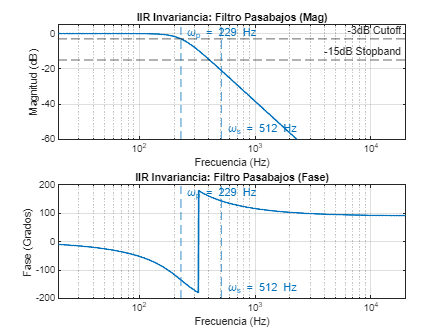

figure(1)
subplot(2,1,1);
semilogx(f_z, 20*log10(abs(h1_i)), 'LineWidth', 1.5);
grid on; title('IIR Invariancia: Filtro Pasabajos (Mag)');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
ylim([-60 5]); xlim([20 fs/2]);
xlim([20 20000]);
label_3 = '-3dB Cutoff';
label_15 = '-15dB Stopband';
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
% Marcadores
label1 = sprintf("\\omega_p = %.0f Hz", fc_1_2);
label2 = sprintf("\\omega_s = %.0f Hz", f0(2));
xline(fc_1_2, '--', label1, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top','HandleVisibility','off');
xline(f0(2), '--', label2, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');

subplot(2,1,2);
semilogx(f_z, rad2deg(angle(h1_i)), 'LineWidth', 1.5);
grid on; title('IIR Invariancia: Filtro Pasabajos (Fase)');
xlabel('Frecuencia (Hz)'); ylabel('Fase (Grados)'); xlim([20 fs/2]);
xline(fc_1_2, '--', label1, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top','HandleVisibility','off');
xline(f0(2), '--', label2, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xlim([20 20000]);

**Bode Filtro 2 (BandPass)**

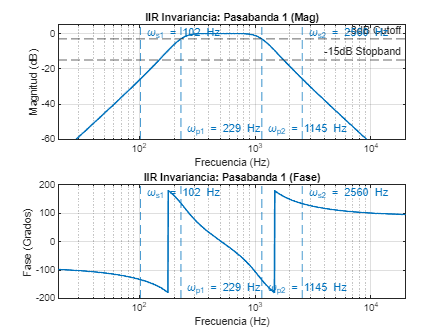

figure(2)
subplot(2,1,1);
semilogx(f_z, 20*log10(abs(h2_i)), 'LineWidth', 1.5);
grid on; title('IIR Invariancia: Pasabanda 1 (Mag)');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
ylim([-60 5]); xlim([20 fs/2]);
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
% Marcadores
label3 = sprintf("\\omega_{p1} = %.0f Hz", fc_1_2);
label4 = sprintf("\\omega_{p2} = %.0f Hz", fc_2_3);
label5 = sprintf("\\omega_{s1} = %.0f Hz", f0(1));
label6 = sprintf("\\omega_{s2} = %.0f Hz", f0(3));
xline(fc_1_2, '--', label3, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_2_3, '--', label4, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(1), '--', label5, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(3), '--', label6, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([20 20000]);

subplot(2,1,2);
semilogx(f_z, rad2deg(angle(h2_i)), 'LineWidth', 1.5);
grid on; title('IIR Invariancia: Pasabanda 1 (Fase)');
xlabel('Frecuencia (Hz)'); ylabel('Fase (Grados)'); xlim([20 fs/2]);
xline(fc_1_2, '--', label3, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_2_3, '--', label4, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(1), '--', label5, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(3), '--', label6, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([20 20000]);

**Bode Filtro 3 (BandPass)**

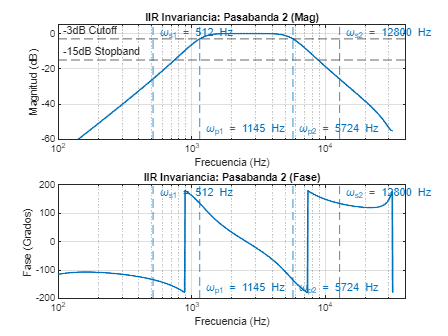

figure(3)
subplot(2,1,1);
semilogx(f_z, 20*log10(abs(h3_i)), 'LineWidth', 1.5);
grid on; title('IIR Invariancia: Pasabanda 2 (Mag)');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
ylim([-60 5]); xlim([20 fs/2]);
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal', 'LabelHorizontal','left','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontal','left','HandleVisibility','off'); % Línea de referencia
% Marcadores
label7 = sprintf("\\omega_{p1} = %.0f Hz", fc_2_3);
label8 = sprintf("\\omega_{p2} = %.0f Hz", fc_3_4);
label9 = sprintf("\\omega_{s1} = %.0f Hz", f0(2));
label10 = sprintf("\\omega_{s2} = %.0f Hz", f0(4));
xline(fc_2_3, '--', label7, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_3_4, '--', label8, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(2), '--', label9, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(4), '--', label10, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 40000]);

subplot(2,1,2);
semilogx(f_z, rad2deg(angle(h3_i)), 'LineWidth', 1.5);
grid on; title('IIR Invariancia: Pasabanda 2 (Fase)');
xlabel('Frecuencia (Hz)'); ylabel('Fase (Grados)'); xlim([20 fs/2]);
xline(fc_2_3, '--', label7, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_3_4, '--', label8, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(2), '--', label9, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(4), '--', label10, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 40000]);

**Filtro 4 (HighPass)**

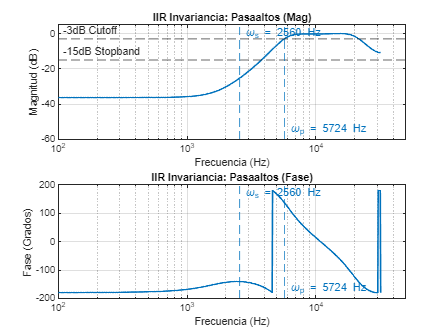

figure(4)
subplot(2,1,1);
semilogx(f_z, 20*log10(abs(h4_i)), 'LineWidth', 1.5);
grid on; title('IIR Invariancia: Pasaaltos (Mag)');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
ylim([-60 5]); xlim([20 fs/2]);
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal', 'LabelHorizontal','left','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontal','left','HandleVisibility','off'); % Línea de referencia
% Marcadores
label11 = sprintf("\\omega_p = %.0f Hz", fc_3_4);
label12 = sprintf("\\omega_s = %.0f Hz", f0(3));
xline(fc_3_4, '--', label11, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(f0(3), '--', label12, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 50000]);

subplot(2,1,2);
semilogx(f_z, rad2deg(angle(h4_i)), 'LineWidth', 1.5);
grid on; title('IIR Invariancia: Pasaaltos (Fase)');
xlabel('Frecuencia (Hz)'); ylabel('Fase (Grados)'); xlim([20 fs/2]);
xline(fc_3_4, '--', label11, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(f0(3), '--', label12, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 50000]);

### Transformación Bilineal

% PARTE B: Método de transformación bilineal
% Prototipos Analógicos en ZPK (z, p, k)
[z1, p1, k1] = butter(N_final, wc_1_2, 's');                
[z2, p2, k2] = butter(N_final, [wc_1_2, wc_2_3], 's');     
[z3, p3, k3] = butter(N_final, [wc_2_3, wc_3_4], 's');     
% Filtro 4 ORIGINAL (Highpass real)
[z4, p4, k4] = butter(N_final, wc_3_4, 'high', 's');

% 2. Transformación Bilineal (ZPK -> ZPK Digital)
[zd1, pd1, kd1] = bilinear(z1, p1, k1, fs);
[zd2, pd2, kd2] = bilinear(z2, p2, k2, fs);
[zd3, pd3, kd3] = bilinear(z3, p3, k3, fs);
[zd4, pd4, kd4] = bilinear(z4, p4, k4, fs);

% Conversión a Secciones de Segundo Orden (SOS)
% Estas matrices 'sos' son las que usaremos para filtrar y graficar
sos1 = zp2sos(zd1, pd1, kd1);
sos2 = zp2sos(zd2, pd2, kd2);
sos3 = zp2sos(zd3, pd3, kd3);
sos4 = zp2sos(zd4, pd4, kd4);

% Calculamos respuesta usando freqz con matriz SOS
h1_b = freqz(sos1, f_z, fs);
h2_b = freqz(sos2, f_z, fs);
h3_b = freqz(sos3, f_z, fs);
h4_b = freqz(sos4, f_z, fs);

**Bode Filtro 1 (LowPass)**

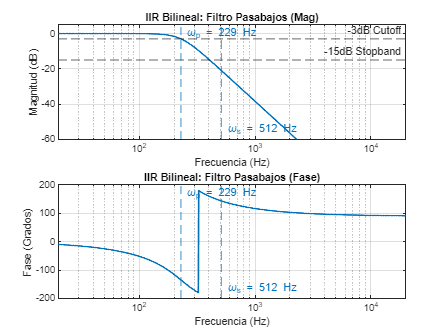

figure(5)
subplot(2,1,1);
semilogx(f_z, 20*log10(abs(h1_b)), 'LineWidth', 1.5);
grid on; title('IIR Bilineal: Filtro Pasabajos (Mag)');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
ylim([-60 5]); xlim([20 fs/2]);
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
xline(fc_1_2, '--', label1, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top','HandleVisibility','off');
xline(f0(2), '--', label2, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xlim([20 20000]);

subplot(2,1,2);
semilogx(f_z, rad2deg(angle(h1_b)), 'LineWidth', 1.5);
grid on; title('IIR Bilineal: Filtro Pasabajos (Fase)');
xlabel('Frecuencia (Hz)'); ylabel('Fase (Grados)'); xlim([20 fs/2]);
xline(fc_1_2, '--', label1, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top','HandleVisibility','off');
xline(f0(2), '--', label2, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xlim([20 20000]);

**Bode Filtro 2 (BandPass)**

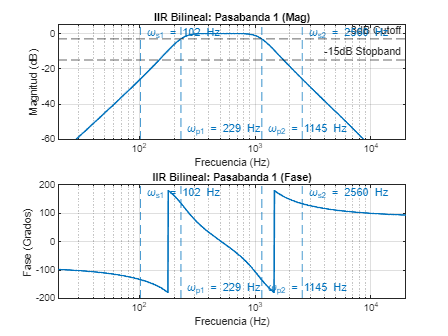

figure(6)
subplot(2,1,1);
semilogx(f_z, 20*log10(abs(h2_b)),  'LineWidth', 1.5);
grid on; title('IIR Bilineal: Pasabanda 1 (Mag)');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
ylim([-60 5]); xlim([20 fs/2]);
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
xline(fc_1_2, '--', label3, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_2_3, '--', label4, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(1), '--', label5, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(3), '--', label6, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([20 20000]);

subplot(2,1,2);
semilogx(f_z, rad2deg(angle(h2_b)), 'LineWidth', 1.5);
grid on; title('IIR Bilineal: Pasabanda 1 (Fase)');
xlabel('Frecuencia (Hz)'); ylabel('Fase (Grados)'); xlim([20 fs/2]);
xline(fc_1_2, '--', label3, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_2_3, '--', label4, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(1), '--', label5, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(3), '--', label6, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([20 20000]);

**Bode Filtro 3 (BandPass)**

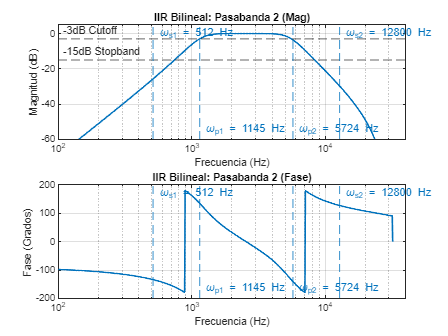

figure(7)
subplot(2,1,1);
semilogx(f_z, 20*log10(abs(h3_b)), 'LineWidth', 1.5);
grid on; title('IIR Bilineal: Pasabanda 2 (Mag)');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
ylim([-60 5]); xlim([20 fs/2]);
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal', 'LabelHorizontal','left','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontal','left','HandleVisibility','off'); % Línea de referencia
xline(fc_2_3, '--', label7, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_3_4, '--', label8, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(2), '--', label9, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(4), '--', label10, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 40000]);

subplot(2,1,2);
semilogx(f_z, rad2deg(angle(h3_b)),'LineWidth', 1.5);
grid on; title('IIR Bilineal: Pasabanda 2 (Fase)');
xlabel('Frecuencia (Hz)'); ylabel('Fase (Grados)'); xlim([20 fs/2]);
xline(fc_2_3, '--', label7, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_3_4, '--', label8, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(2), '--', label9, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(4), '--', label10, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 40000]);

**Filtro 4 (HighPass)**

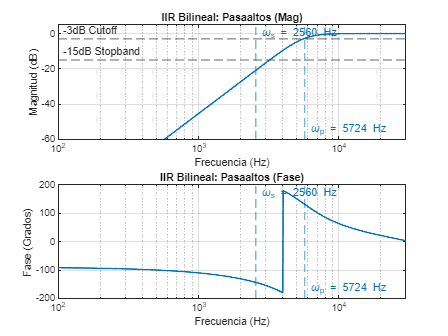

figure(8)
subplot(2,1,1);
semilogx(f_z, 20*log10(abs(h4_b)), 'LineWidth', 1.5);
grid on; title('IIR Bilineal: Pasaaltos (Mag)');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
ylim([-60 5]); xlim([20 fs/2]);
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal', 'LabelHorizontal','left','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontal','left','HandleVisibility','off'); % Línea de referencia
xline(fc_3_4, '--', label11, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(f0(3), '--', label12, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 30000]);

subplot(2,1,2);
semilogx(f_z, rad2deg(angle(h4_b)), 'LineWidth', 1.5);
grid on; title('IIR Bilineal: Pasaaltos (Fase)');
xlabel('Frecuencia (Hz)'); ylabel('Fase (Grados)'); xlim([20 fs/2]);
xline(fc_3_4, '--', label11, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(f0(3), '--', label12, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 30000]);

### Graficas completas

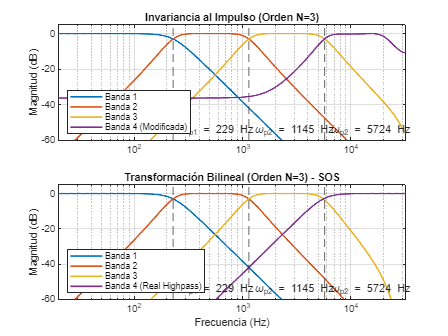

f_z = logspace(log10(20), log10(fs/2), 1000);
figure(9)
% Subplot 1: Invariancia al Impulso
subplot(2,1,1);

semilogx(f_z, 20*log10(abs(h1_i)), 'LineWidth', 1.5); hold on;
semilogx(f_z, 20*log10(abs(h2_i)), 'LineWidth', 1.5);
semilogx(f_z, 20*log10(abs(h3_i)), 'LineWidth', 1.5);
semilogx(f_z, 20*log10(abs(h4_i)), 'LineWidth', 1.5);
title(['Invariancia al Impulso (Orden N=' num2str(N_final) ')']);
ylabel('Magnitud (dB)'); grid on; xlim([20 fs/2]); ylim([-60 5]);
legend('Banda 1', 'Banda 2', 'Banda 3', 'Banda 4 (Modificada)', "Location", "southwest");
xline(fc_1_2, '--', label3,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_2_3, '--', label4,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_3_4, '--', label8,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');


% Subplot 2: Transformación Bilineal
subplot(2,1,2);

semilogx(f_z, 20*log10(abs(h1_b)), 'LineWidth', 1.5); hold on;
semilogx(f_z, 20*log10(abs(h2_b)), 'LineWidth', 1.5);
semilogx(f_z, 20*log10(abs(h3_b)), 'LineWidth', 1.5);
semilogx(f_z, 20*log10(abs(h4_b)), 'LineWidth', 1.5);
title(['Transformación Bilineal (Orden N=' num2str(N_final) ') - SOS']);
ylabel('Magnitud (dB)'); xlabel('Frecuencia (Hz)'); 
grid on; xlim([20 fs/2]); ylim([-60 5]);
legend('Banda 1', 'Banda 2', 'Banda 3', 'Banda 4 (Real Highpass)', "Location", "southwest");
xline(fc_1_2, '--', label3,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_2_3, '--', label4,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_3_4, '--', label8,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');

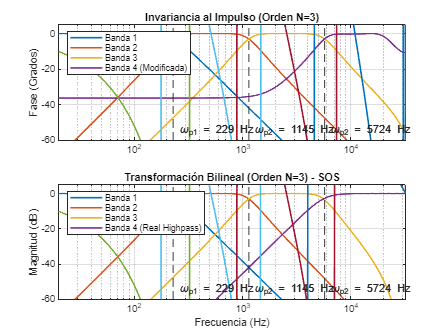

figure(10)
% Subplot 1: Invariancia al Impulso
subplot(2,1,1);

semilogx(f_z, rad2deg(angle(h1_i)), 'LineWidth', 1.5); hold on;
semilogx(f_z, rad2deg(angle(h2_i)), 'LineWidth', 1.5);
semilogx(f_z, rad2deg(angle(h3_i)), 'LineWidth', 1.5);
semilogx(f_z, rad2deg(angle(h4_i)), 'LineWidth', 1.5);
title(['Invariancia al Impulso (Orden N=' num2str(N_final) ')']);
ylabel('Fase (Grados)'); grid on; xlim([20 fs/2]); 
legend('Banda 1', 'Banda 2', 'Banda 3', 'Banda 4 (Modificada)', "Location", "northwest");
xline(fc_1_2, '--', label3,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_2_3, '--', label4,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_3_4, '--', label8,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');


% Subplot 2: Transformación Bilineal
subplot(2,1,2);

semilogx(f_z, rad2deg(angle(h1_b)), 'LineWidth', 1.5); hold on;
semilogx(f_z, rad2deg(angle(h2_b)), 'LineWidth', 1.5);
semilogx(f_z, rad2deg(angle(h3_b)), 'LineWidth', 1.5);
semilogx(f_z, rad2deg(angle(h4_b)), 'LineWidth', 1.5);
title(['Transformación Bilineal (Orden N=' num2str(N_final) ') - SOS']);
ylabel('Magnitud (dB)'); xlabel('Frecuencia (Hz)'); 
grid on; xlim([20 fs/2]); 
legend('Banda 1', 'Banda 2', 'Banda 3', 'Banda 4 (Real Highpass)', "Location", "northwest");
xline(fc_1_2, '--', label3,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_2_3, '--', label4,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_3_4, '--', label8,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');